# EE 141: Digital Signal Processing

# Lab 5: Discrete-time Processing of Continuous Signals

# Lab Section: 022

# Name: Buddy Ugwumba 

# SID: 862063029

## Objective:

The purpose of this lab is to process simple, artifically generated, continuous-time signals in discrete time. The generation of these continuous-time signals in dsicrete-time will include a differentiator and a delay element.

### Question 1 (Differentiator):

Let


$$x_c \left(t\right)=\mathrm{cos}\left(10\pi t\right)+\frac{1}{2}\mathrm{cos}\left(5\pi t\right)-\frac{1}{4}\mathrm{cos}\left(20\pi t\right)$$


and create $x\left\lbrack n\right\rbrack$ for $0\le n\le 300$ by sampling $x_c \left(t\right)$ with a period of $T=0\ldotp 01$ secs. 

% Step 1: sample the continuous time signal x_c(t)
n = 0:300;
T = 0.01; % Sampling Period
t = n*T; % t is the point in s_c(t)

% Step 2: Get the discrete-time input, input
x_ct = cos((10*pi)*(t))+(0.5*cos((5*pi)*(t)))-(0.25*cos((20*pi)*(t)));

% Step 3: Truncate h[n] n ==> h_{hat}(n) filter
N = 1;
for n = 0:(2*N)
    if n==N
        truncated_H(n+1)=0;
    else
        truncated_H(n+1) = ((-1)^(n-N))/((n-N)*T);
    end
end

% Step 4: get the output y[n]

#### a) Let $N=1$. Perform the convolution $y\left\lbrack n\right\rbrack =x\left\lbrack n\right\rbrack \star h\left\lbrack n\right\rbrack$ using the command conv. 

y_n = conv(x_ct, truncated_H);

#### b) Analytically calculate $y_{c\;} \left(t\right)$ using (1) and (2)

diff = t -(N.*T);
% Differentiation of x_c(t)
y_ct = (-10*pi*sin((10*pi).*diff))+(.5*-5*pi*sin((5*pi).*diff))-(0.25*-20*pi*sin((20*pi).*diff));

#### c) Compare $\hat{y} \left\lbrack n\right\rbrack$ with $y\left\lbrack n\right\rbrack =y_c \left(\mathrm{nT}\right)$ by plotting $y\left\lbrack n\right\rbrack$ and $\hat{y} \left\lbrack n\right\rbrack$ on the same graph. Other than the "transient" effects yoou see on the plot of $\hat{y} \left\lbrack n\right\rbrack$ around the borders, do $y\left\lbrack n\right\rbrack$ and $\hat{y} \left\lbrack n\right\rbrack$ agree?

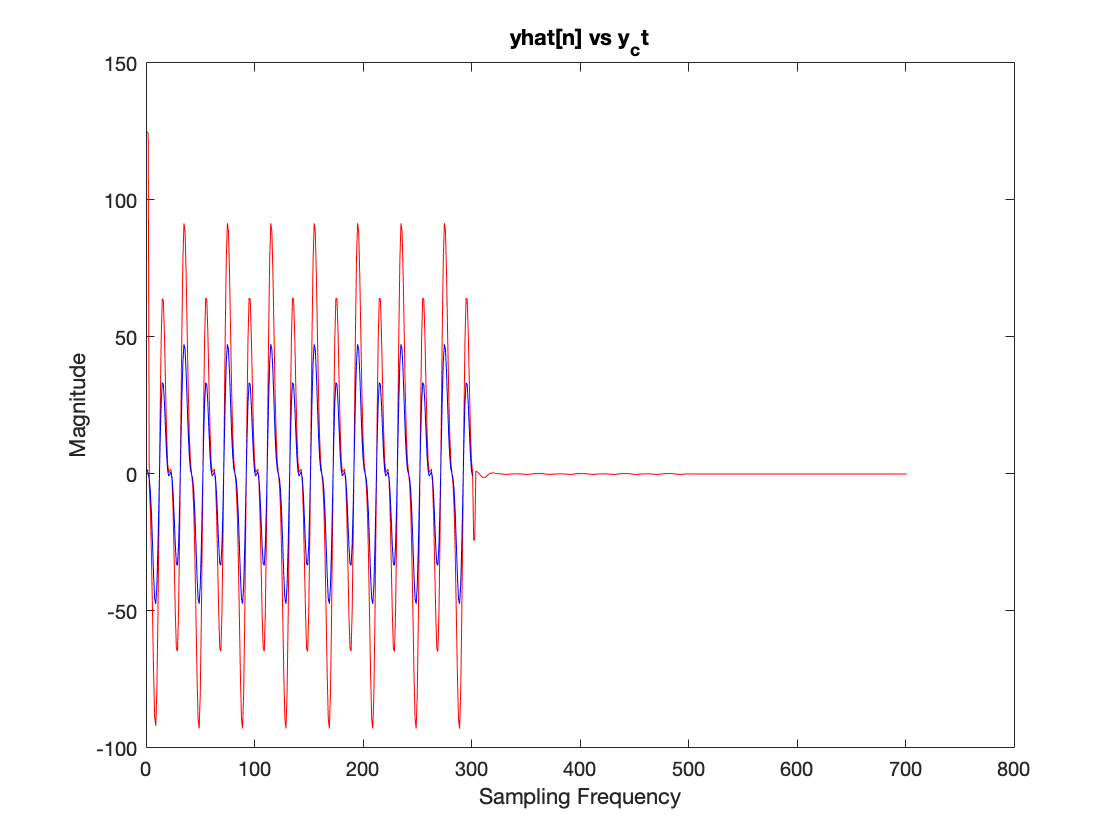

figure(1)

% Convolution 
plot(y_n,'red')
hold on
% equation
plot(y_ct,'blue')
hold off
title('yhat[n] vs y_ct')
xlabel('Sampling Frequency')
ylabel('Magnitude')

The graphs $y\left\lbrack n\right\rbrack$ and $\hat{y} \left\lbrack n\right\rbrack$ agree in shape, but do not agree in amplitude. This is because my value for N is not large enough. 

#### d) If they did not agree, your approximation $\hat{h} \left\lbrack n\right\rbrack$ must be too crude. Increase $N$and redo a through c until they $y\left\lbrack n\right\rbrack$ and $\hat{y} \left\lbrack n\right\rbrack$ more or less agree. (You should not have to increase N beyond 20)

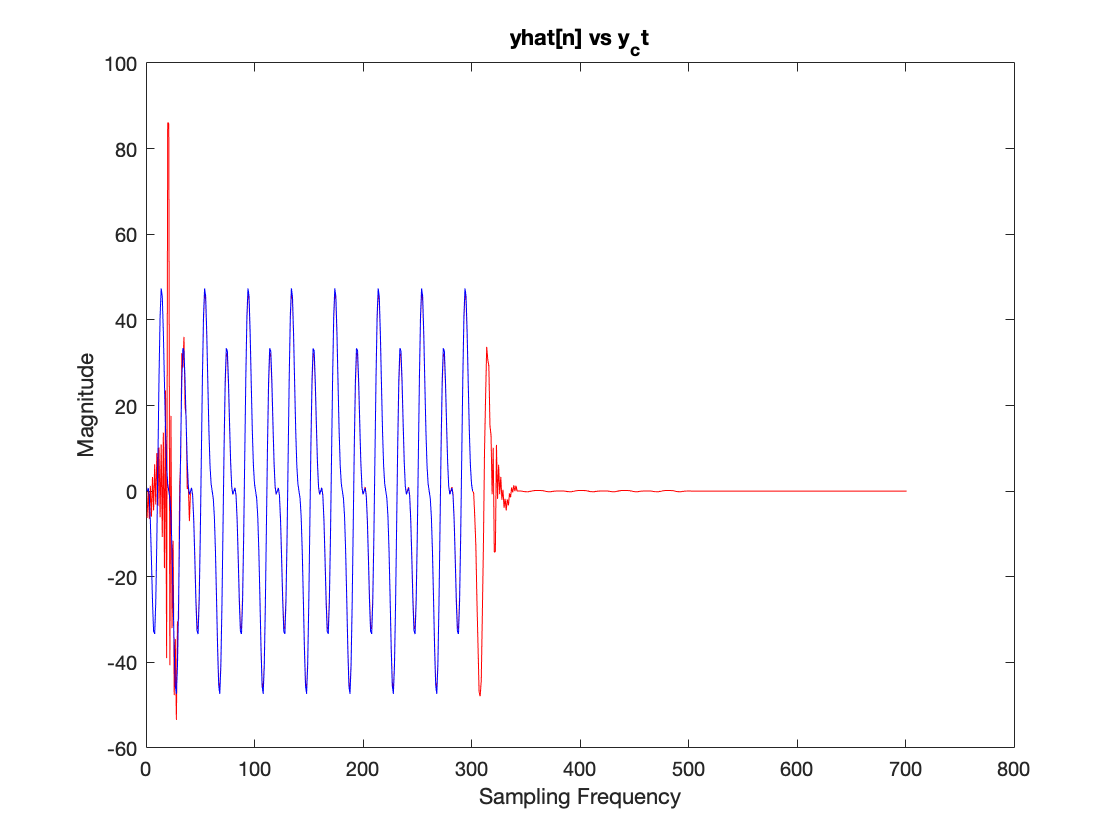

% a
N = 20;
for n = 0:(2*N)
    if n==N
        truncated_H(n+1)=0;
    else
        truncated_H(n+1) = ((-1)^(n-N))/((n-N)*T);
    end
end

y_n = conv(x_ct, truncated_H);

diff = t -(N.*T);
% Differentiation of x_c(t)
y_ct = (-10*pi*sin((10*pi).*diff))+(.5*-5*pi*sin((5*pi).*diff))-(0.25*-20*pi*sin((20*pi).*diff));

% c
figure(1)

% Convolution 
plot(y_n, 'red')
hold on
% equation
plot(y_ct, 'blue')
hold off
title('yhat[n] vs y_ct')
xlabel('Sampling Frequency')
ylabel('Magnitude')

### Question 2 (Fractional Sample Delay):

Let


$$x_c \left(t\right)=\cos \left(2\pi t\right)$$


and create $x\left\lbrack n\right\rbrack$ for $0\le n\le 300$ by sampling $x_c \left(t\right)$ with a period of $T=0\ldotp 1$ secs. 

% Step 1: sample the continuous time signal x_c(t)
n = 0:300;
T = 0.1; % Sampling Period
t = n*T; % t is the point in s_c(t)

% Step 2: Get the discrete-time input, input
x_ct = cos((2*pi)*(t));

% Step 3: Truncate h[n] n ==> h_{hat}(n) filter
N = 15;
for n = 0:(2*N)
    if(n<0 || n>2*N)
        truncated_H(n+1)=0;
    else
        truncated_H(n+1) = sinc(pi*(n-N-0.03));
    end
end

% Step 4: get the output y[n]

#### a) Let $N=1$. Perform the convolution $y\left\lbrack n\right\rbrack =x\left\lbrack n\right\rbrack \star h\left\lbrack n\right\rbrack$ using the command conv. 

y_n = conv(x_ct, truncated_H);

#### b) Analytically calculate $y_{c\;} \left(t\right)$ using (1) and (2)

delta = 0.03;
% Differentiation of x_c(t)
y_ct = cos((2*pi)*(t-(N*T)-delta));

#### c) Compare $\hat{y} \left\lbrack n\right\rbrack$ with $y\left\lbrack n\right\rbrack =y_c \left(\mathrm{nT}\right)$ by plotting $y\left\lbrack n\right\rbrack$ and $\hat{y} \left\lbrack n\right\rbrack$ on the same graph. Other than the "transient" effects yoou see on the plot of $\hat{y} \left\lbrack n\right\rbrack$ around the borders, do $y\left\lbrack n\right\rbrack$ and $\hat{y} \left\lbrack n\right\rbrack$ agree?

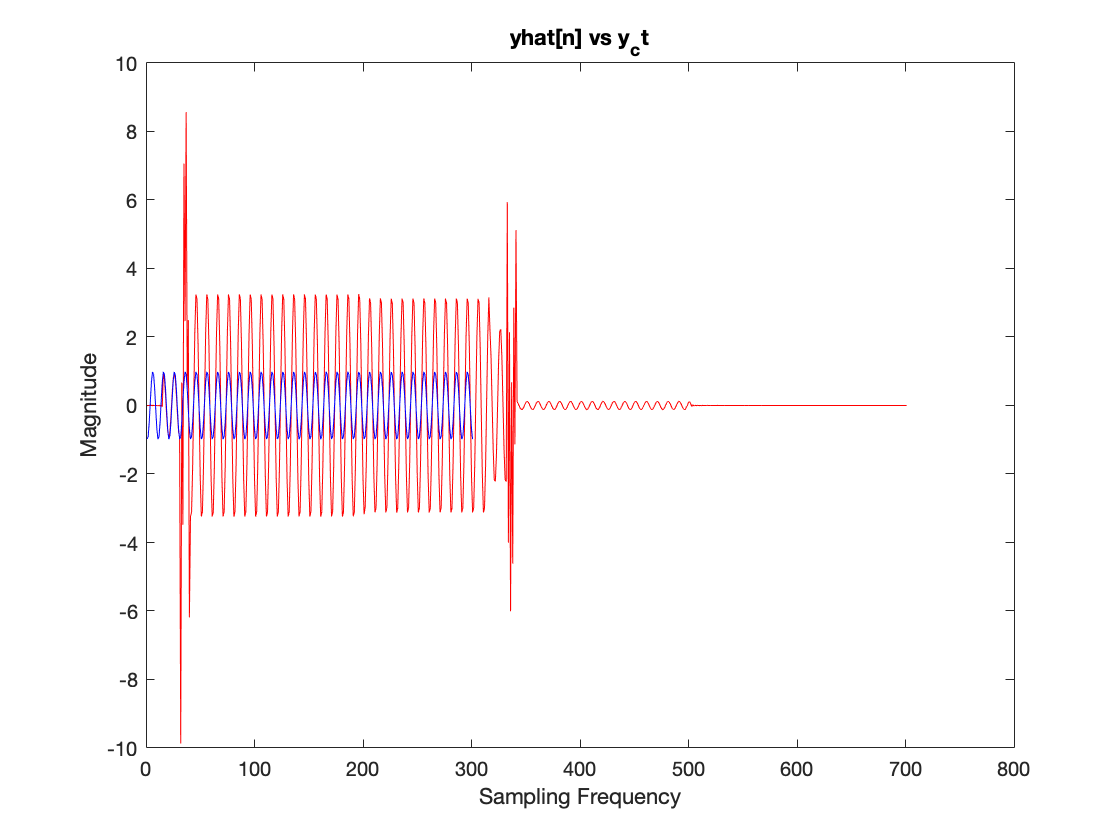

figure(1)

% Convolution 
plot(y_n,'red')
hold on
% equation
plot(y_ct,'blue')
hold off
title('yhat[n] vs y_ct')
xlabel('Sampling Frequency')
ylabel('Magnitude')

The graphs $y\left\lbrack n\right\rbrack$ and $\hat{y} \left\lbrack n\right\rbrack$ agree in shape, but do not agree in amplitude. This is because my value for N is not large enough. 

#### d) If they did not agree, your approximation $\hat{h} \left\lbrack n\right\rbrack$ must be too crude. Increase $N$and redo a through c until they $y\left\lbrack n\right\rbrack$ and $\hat{y} \left\lbrack n\right\rbrack$ more or less agree. (You should not have to increase N beyond 20)

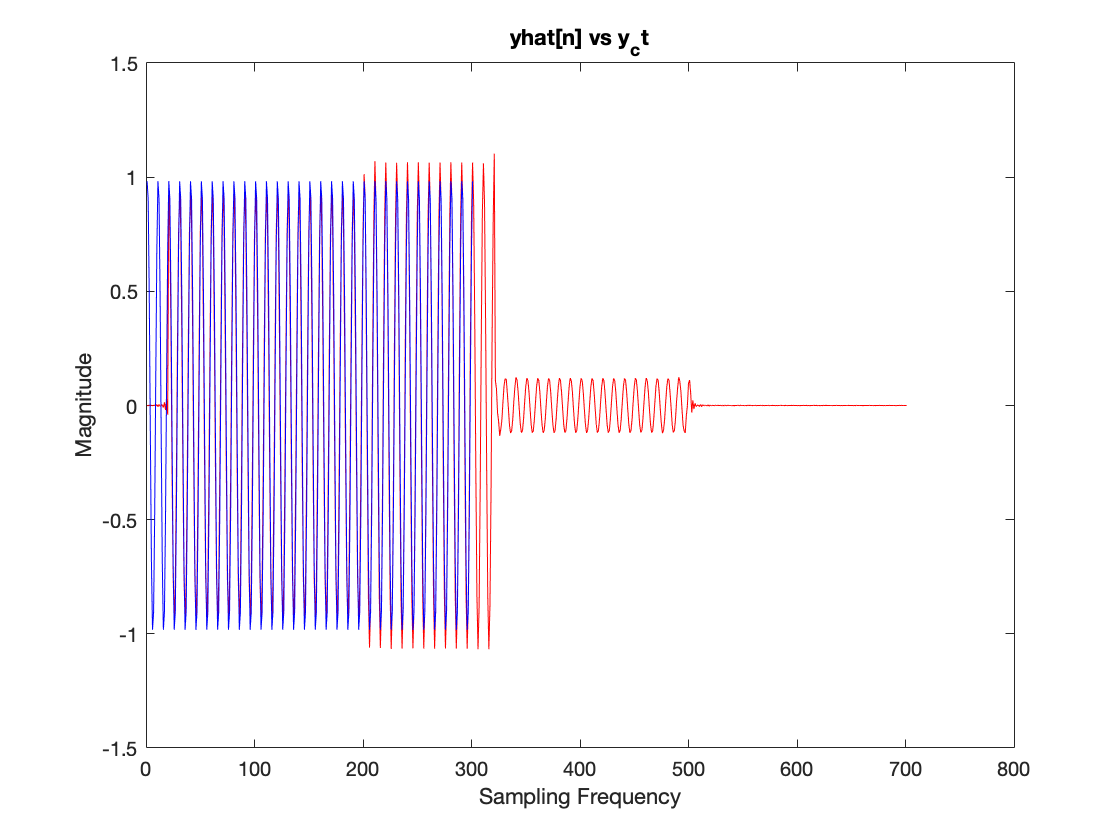

N = 20;
for n = 0:(2*N)
    if((n < 0) || (n>(2*N)))
        truncated_H(n+1)=0;
    else
        truncated_H(n+1) = sinc(pi*(n-N-0.03));
    end
end

y_n = conv(x_ct, truncated_H);

delta = 0.03;
% Differentiation of x_c(t)
y_ct = cos((2*pi)*(t-(N.*T)-delta));

figure(1)

% Convolution 
plot(y_n,'red')
hold on
% equation
plot(y_ct,'blue')
hold off
title('yhat[n] vs y_ct')
xlabel('Sampling Frequency')
ylabel('Magnitude')